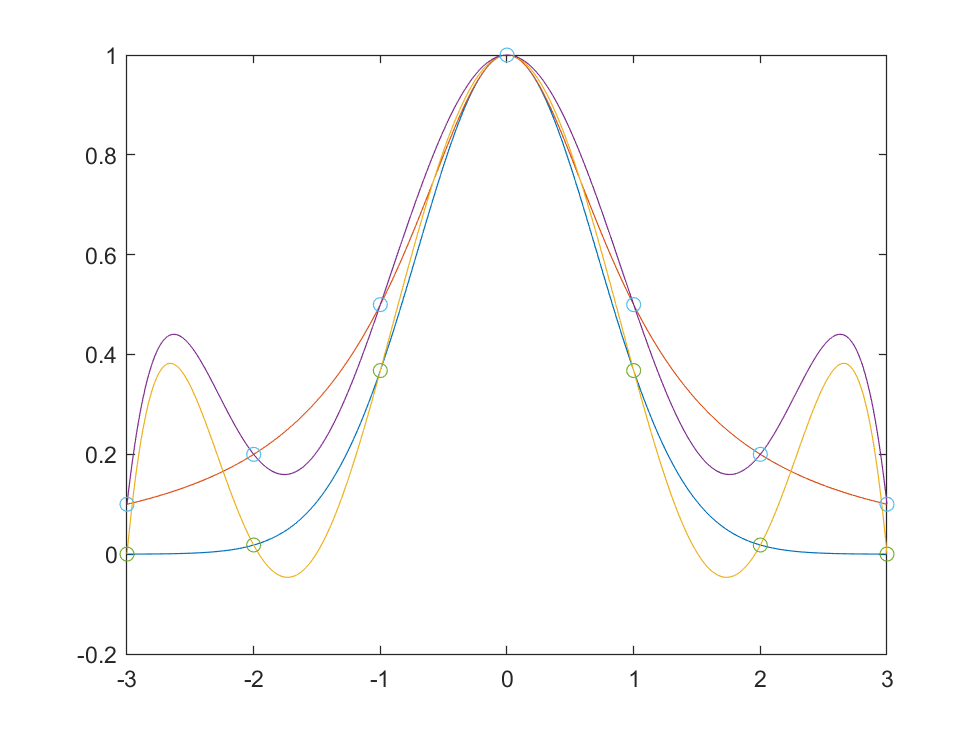

% experiment 1
% function f1
f1 =@(x) (exp(-x.^2));

% data points of f1
datx = -3:1:3;
daty = f1(datx);

% points to interpolate f1
x = -3:0.01:3;

% Lagrange interpolant of f1
P1 = Lagrange_poly(x,datx,daty);

% function f2
f2 =@(x) (1./(1+x.^2));

% data points of f2
datx = -3:1:3;
daty = f2(datx);

% points to interpolate f2
x = -3:0.01:3;

% Lagrange interpolant of f2
P2 = Lagrange_poly(x,datx,daty);

% plot of the functions
plot(x,f1(x),x,f2(x));
hold on;

% plot of the two interpolants
plot(x',P1,x',P2);

% plot of the data set
scatter(datx,f1(datx));
scatter(datx,f2(datx));
hold off;

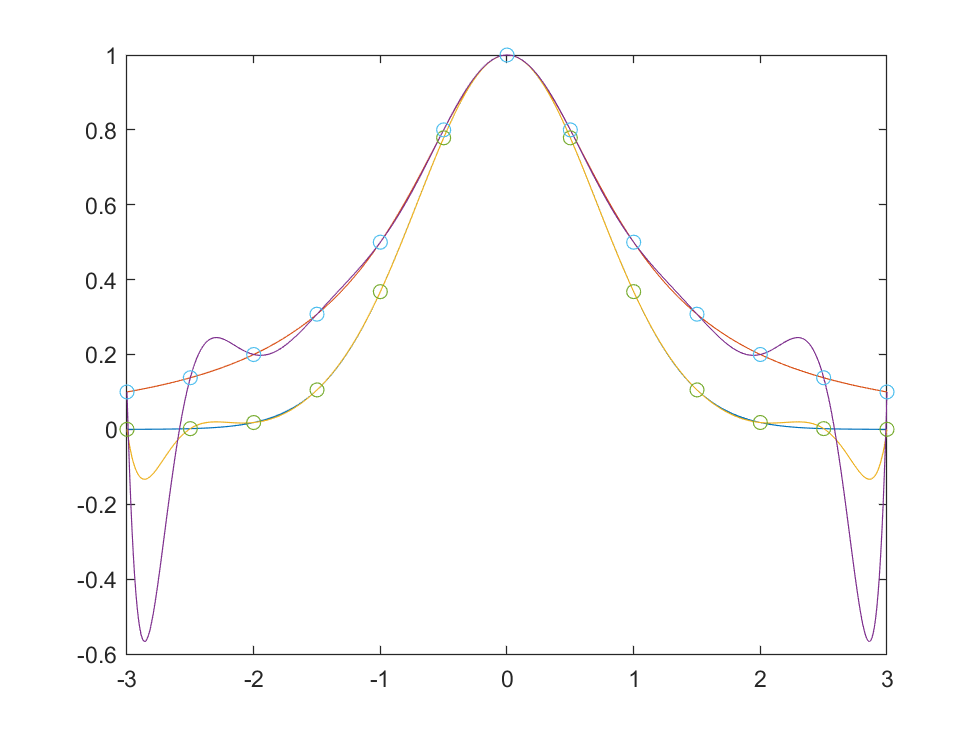


% experiment 2
% function f1
f1 =@(x) (exp(-x.^2));

% data points of f1
datx = -3:0.5:3;
daty = f1(datx);

% points to interpolate f1
x = -3:0.01:3;

% Lagrange interpolant of f1
P3 = Lagrange_poly(x,datx,daty);

% function f2
f2 =@(x) (1./(1+x.^2));

% data points of f2
datx = -3:0.5:3;
daty = f2(datx);

% points to interpolate f2
x = -3:0.01:3;

% Lagrange interpolant of f2
P4 = Lagrange_poly(x,datx,daty);

% plot of the functions
plot(x,f1(x),x,f2(x));
hold on;

% plot of the two interpolants
plot(x',P3,x',P4);

% plot of the data set
scatter(datx,f1(datx));
scatter(datx,f2(datx));
hold off;

function [y] = Lagrange_poly(x,datx,daty)
    y = 0;
    sx = size(x,2);
    sdatx = size(datx,2);
    L = ones(sdatx,sx);
    for i = 1:sdatx
        for j = 1:sdatx
            if(i ~= j)
                L(i,:) = L(i,:).*(x-datx(j))/(datx(i)-datx(j));
            end
        end
    end
    for i = 1:sdatx
        y = y + daty(i) * L(i,:);
    end
    y = y';
end
